## **In the name of God**

# Digital Signal Processing

# Computer Assignment #2

# **Alireza Javid**

# **810198375**

Part 1: ***Short-time Fourier Transform***

a) ***import data:***

[teletext,fs] = audioread('teletext.wav');

b ) `Power Spectrum Representation:`

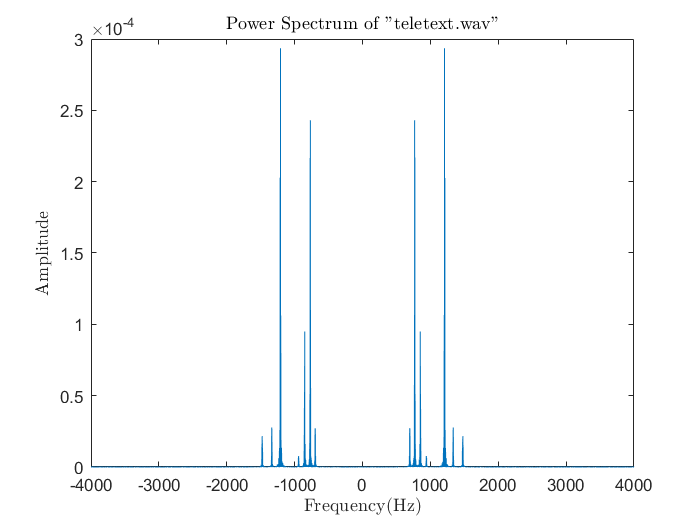

t = 0:1/fs:(length(teletext)-1)/fs;
f = -fs/2:fs/length(t):(fs/2-1/length(t));
TEX_f = fftshift(fft(teletext))/length(teletext);
PS_TEX = abs(TEX_f).^2;
plot(f,abs(PS_TEX));
title('Power Spectrum of "teletext.wav"','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Amplitude','Interpreter','latex');

c ) ***spectrogram:***

`Test1. `$\textrm{window}-\textrm{size}=100\;\;,\;\textrm{noverlap}=10\;\;,\;\textrm{nfft}=1000$

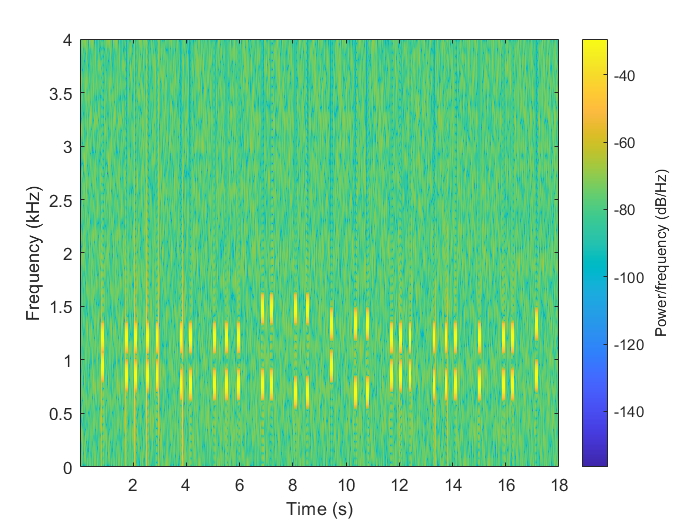

spectrogram(teletext,100,10,1000,fs,'yaxis');

`Test2. `$\textrm{window}-\textrm{size}=1000\;\;,\;\textrm{noverlap}=10\;\;,\;\textrm{nfft}=10000$

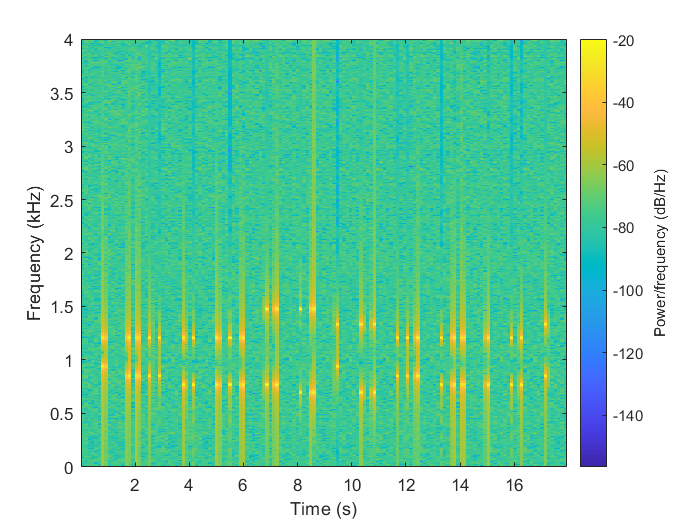

spectrogram(teletext,1000,10,10000,fs,'yaxis');

`Test3. `$\textrm{window}-\textrm{size}=10000\;,\;\textrm{noverlap}=10\;\;,\;\textrm{nfft}=10000$

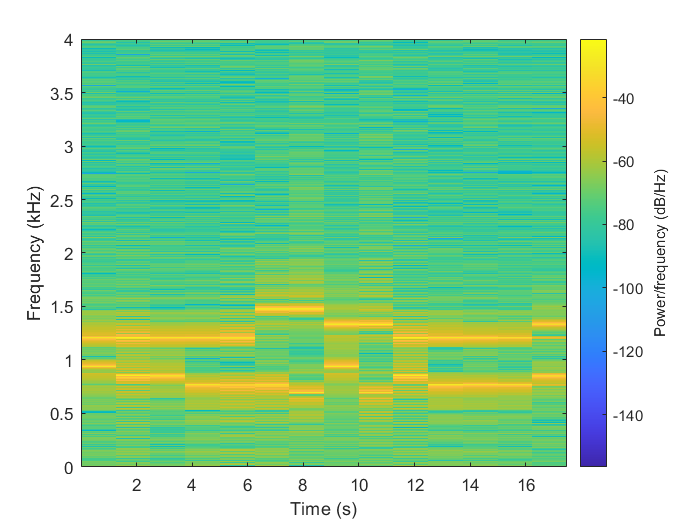

spectrogram(teletext,10000,10,10000,fs,'yaxis');

`Test4. `$\textrm{window}-\textrm{size}=100000\;\;,\;\textrm{noverlap}=100\;\;,\;\textrm{nfft}=10000$

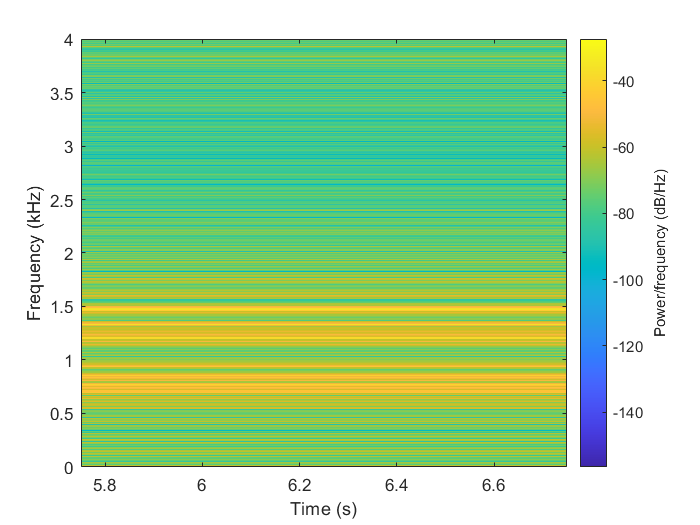

spectrogram(teletext,100000,100,10000,fs,'yaxis');

`Final Test. `$\textrm{window}-\textrm{size}=3000\;\;,\;\textrm{noverlap}=1000\;\;,\;\textrm{nfft}=1500$

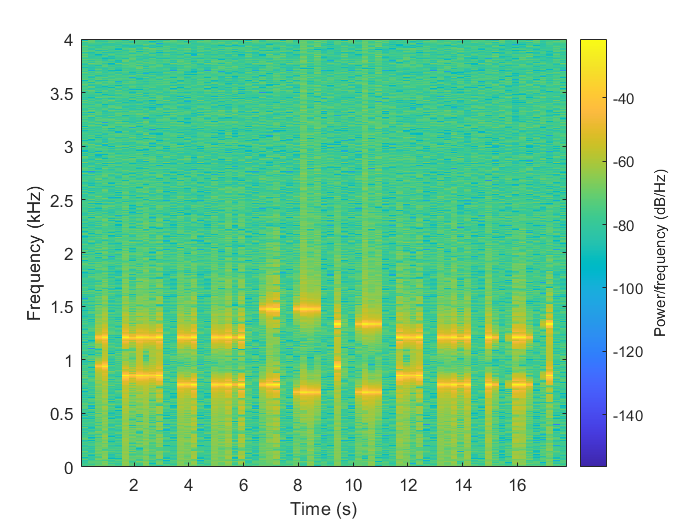

spectrogram(teletext,3000,1000,1500,fs,'yaxis');

Part 2: ***Language Frequency Difference***

a) ***import data:***

[arab_f,fs1] = audioread('Speech samples\AR_F_GadaB.wav');
[arab_m,fs2] = audioread('Speech samples\AR_M_AhmedH.wav');
[fre_f,fs3] = audioread('Speech samples\FRE_F_FabienneP.wav');
[fre_m,fs4] = audioread('Speech samples\FRE_M_JeanNL_Commercial.wav');

b)  `Power Spectrum Representation:`

`i) Arab Female Voice:`

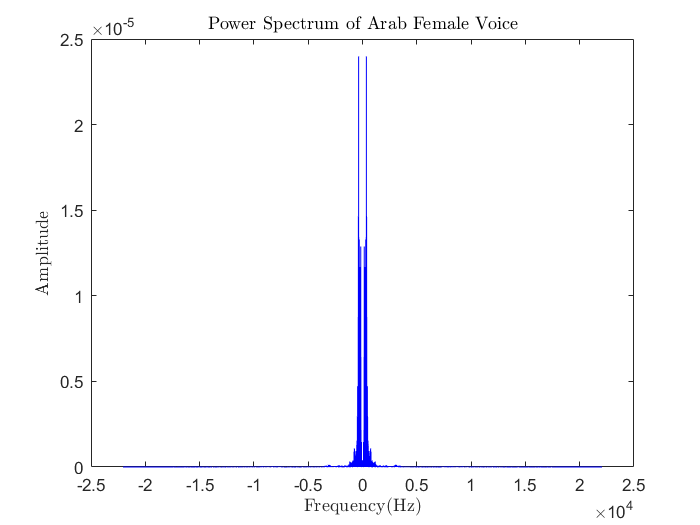

t = 0:1/fs1:(length(arab_f)-1)/fs1;
f = -fs1/2:fs1/length(t):(fs1/2-1/length(t));
ARF_f = fftshift(fft(arab_f))/length(arab_f);
PS_ARF = abs(ARF_f).^2;
plot(f,abs(PS_ARF),'b');
title('Power Spectrum of Arab Female Voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Amplitude','Interpreter','latex');

`ii) Arab Male Voice:`

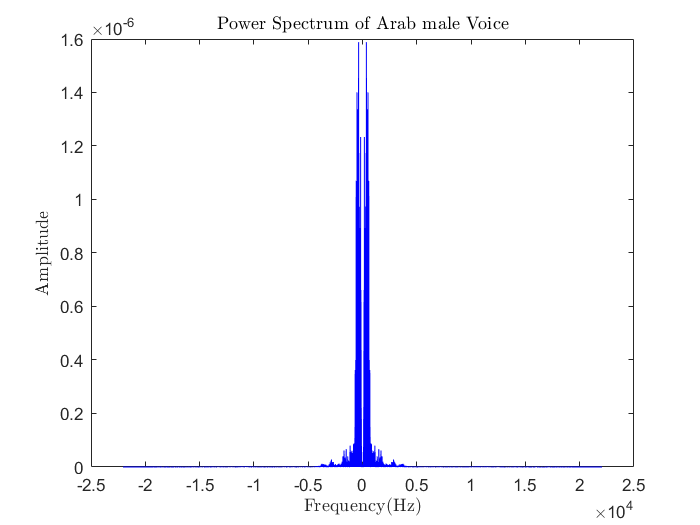

t = 0:1/fs2:(length(arab_m)-1)/fs2;
f = -fs2/2:fs2/length(t):(fs2/2-1/length(t));
ARM_f = fftshift(fft(arab_m))/length(arab_m);
PS_ARM = abs(ARM_f).^2;
plot(f,abs(PS_ARM),'b');
title('Power Spectrum of Arab male Voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Amplitude','Interpreter','latex');

`iii) French Female Voice:`

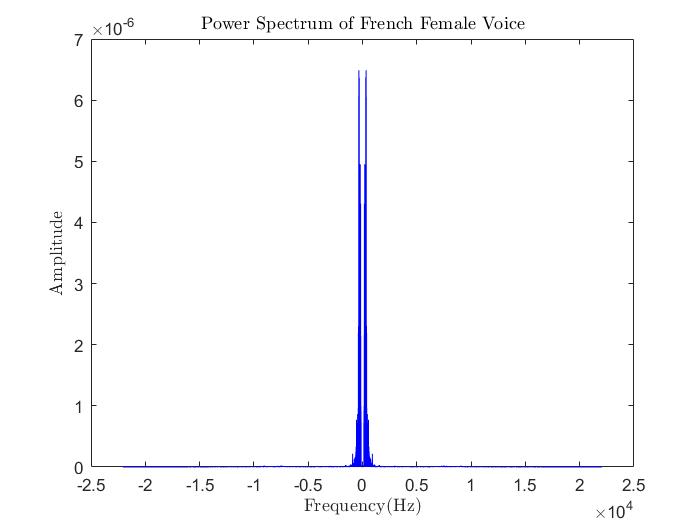

t = 0:1/fs3:(length(fre_f)-1)/fs3;
f = -fs3/2:fs3/length(t):(fs3/2-1/length(t));
FRF_f = fftshift(fft(fre_f))/length(fre_f);
PS_FRF = abs(FRF_f).^2;
plot(f,abs(PS_FRF),'b');
title('Power Spectrum of French Female Voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Amplitude','Interpreter','latex');

`iv) French Male Voice:`

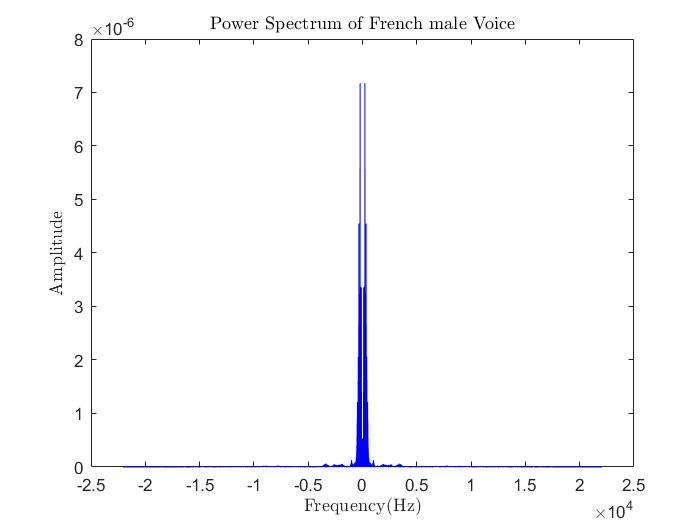

t = 0:1/fs4:(length(fre_m)-1)/fs4;
f = -fs4/2:fs4/length(t):(fs4/2-1/length(t));
FRM_f = fftshift(fft(fre_m))/length(fre_m);
PS_FRM = abs(FRM_f).^2;
plot(f,abs(PS_FRM),'b');
title('Power Spectrum of French male Voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Amplitude','Interpreter','latex');

b) ***Filtering signals:***

`i) Arab Female Voice:`

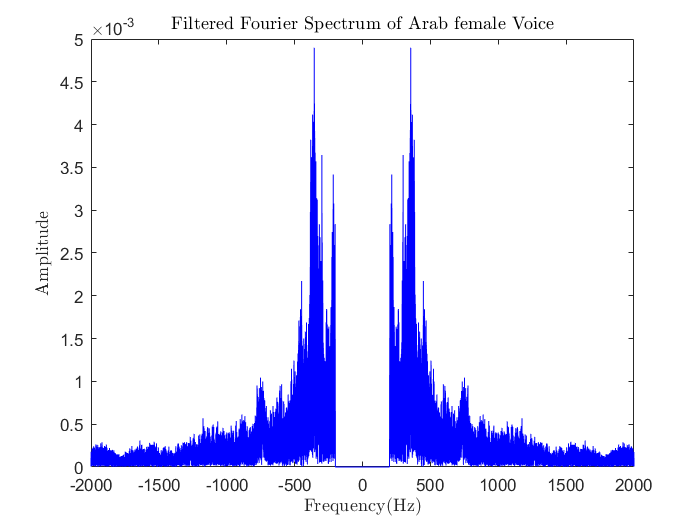

t = 0:1/fs1:(length(arab_f)-1)/fs1;
f = -fs1/2:fs1/length(t):(fs1/2-1/length(t));
bp_filter = zeros(length(PS_ARF), 1);
for i=1:length(bp_filter)
    if (f(i) < 3500 && f(i) > 200) || (f(i) > -3500 && f(i) < -200)
        bp_filter(i) = 1;
    end
end
ARF_filtred = bp_filter .* ARF_f;
plot(f,abs(ARF_filtred),'b');
xlim([-2000,2000])
ylim([0,0.005])
title('Filtered Fourier Spectrum of Arab female Voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Amplitude','Interpreter','latex');

***Filtered Time signal:***

arab_f_filtered = ifft(ifftshift(ARF_filtred)) * length(arab_f);
sound(arab_f_filtered,fs1)

`ii) Arab Male Voice:`

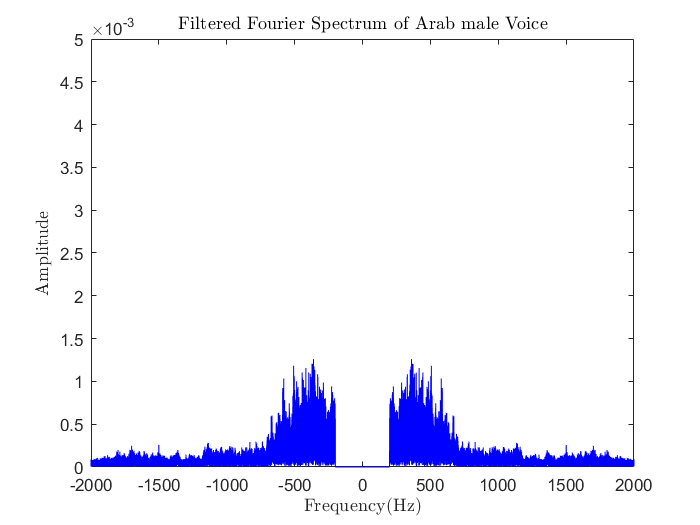

t = 0:1/fs2:(length(arab_m)-1)/fs2;
f = -fs2/2:fs2/length(t):(fs2/2-1/length(t));
bp_filter = zeros(length(PS_ARM), 1);
for i=1:length(bp_filter)
    if (f(i) < 3500 && f(i) > 200) || (f(i) > -3500 && f(i) < -200)
        bp_filter(i) = 1;
    end
end
ARM_filtred = bp_filter .* ARM_f;
plot(f,abs(ARM_filtred),'b');
xlim([-2000,2000])
ylim([0,0.005])
title('Filtered Fourier Spectrum of Arab male Voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Amplitude','Interpreter','latex');

***Filtered Time signal:***

arab_m_filtered = ifft(ifftshift(ARM_filtred)) * length(arab_m);
sound(arab_m_filtered,fs2)

`iii) French Female Voice:`

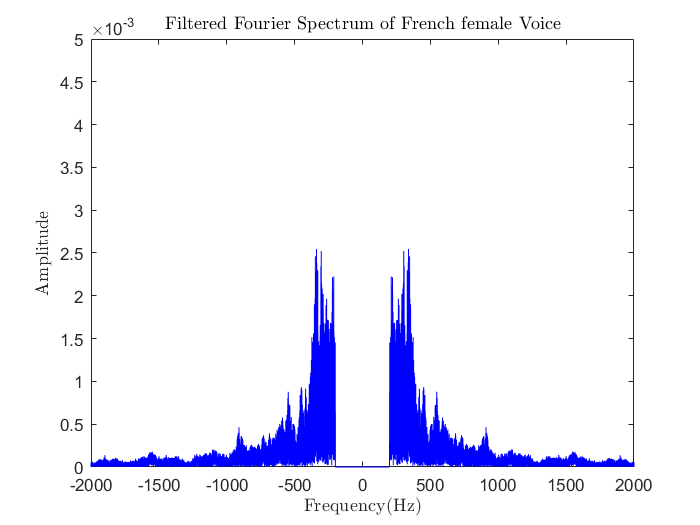

t = 0:1/fs3:(length(fre_f)-1)/fs3;
f = -fs3/2:fs3/length(t):(fs3/2-1/length(t));
bp_filter = zeros(length(PS_FRF), 1);
for i=1:length(bp_filter)
    if (f(i) < 3500 && f(i) > 200) || (f(i) > -3500 && f(i) < -200)
        bp_filter(i) = 1;
    end
end
FRF_filtred = bp_filter .* FRF_f;
plot(f,abs(FRF_filtred),'b');
xlim([-2000,2000])
ylim([0,0.005])
title('Filtered Fourier Spectrum of French female Voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Amplitude','Interpreter','latex');

***Filtered Time signal:***

fre_f_filtered = ifft(ifftshift(FRF_filtred)) * length(fre_f);
sound(fre_f_filtered,fs3)

`iv) French Male Voice:`

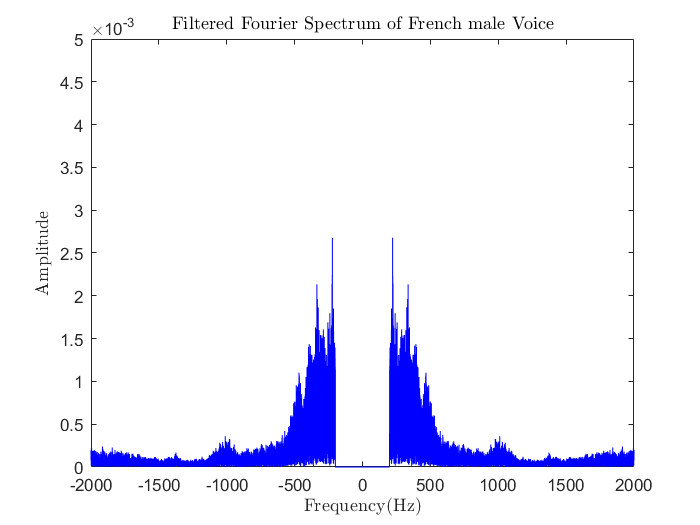

t = 0:1/fs4:(length(fre_m)-1)/fs4;
f = -fs4/2:fs4/length(t):(fs4/2-1/length(t));
bp_filter = zeros(length(PS_FRM), 1);
for i=1:length(bp_filter)
    if (f(i) < 3500 && f(i) > 200) || (f(i) > -3500 && f(i) < -200)
        bp_filter(i) = 1;
    end
end
FRM_filtred = bp_filter .* FRM_f;
plot(f,abs(FRM_filtred),'b');
xlim([-2000,2000])
ylim([0,0.005])
title('Filtered Fourier Spectrum of French male Voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Amplitude','Interpreter','latex');

***Filtered Time signal:***

fre_m_filtered = ifft(ifftshift(FRM_filtred)) * length(fre_m);
sound(fre_m_filtered,fs4)